# Synthesis of the connection of three pipes

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_3_pipes_height_38um_pulse_5s_rectangular_tetrazine_Design_1');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_3_pipes_height_38um_pulse_5s_rectangular_tetrazine_Design_1


#### Parameters

%call to the parameters file
Parameters

p0 = 600

Q_inlet_CNN = 3.3333e-11

mu = 9.9792e-04

D_coeff = 4.9000e-10

Q = 3.3333e-11

#### Péclet condition

Pe_cond=zeros(length(w_vec),length(l_vec));

Q_min=inf;
Q_max=-inf;

for i_w=1:length(w_vec)

    %i_r/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Hydraulic Resistance
        R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));
        
        %Volumetric flow
        Q=p0/R;

        %Mean velocity
        %Circular channel of radius r_vec(i_r) [2, pag. 54]
        % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q/(w_vec(i_w)*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        D_eff=D_coeff*(1+1/200*Pe^2);

        % %Péclet number, circular channel this evaluation follows [1,Eq. (4.44) pp.75]
        % Pe=r_vec(i_r)*v_char/D_coeff;
        
        %Validating the diffusion within the pipe
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            Pe_cond(i_w,i_l)=1;

            if(Q<Q_min)
                Q_min=Q;
                Q_min_w_idx=i_w;
                Q_min_l_idx=i_l;
            end

            if(Q>Q_max)
                Q_max=Q;
                Q_max_w_idx=i_w;
                Q_max_l_idx=i_l;
            end

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            Pe_cond(i_w,i_l)=0;
        
        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            Pe_cond(i_w,i_l)=-1;
        end
    end
end

disp(['Q_min=',num2str(Q_min*6e10),' uL/min'])

Q_min=0.41823 uL/min


disp(['Q_max=',num2str(Q_max*6e10),' uL/min'])

Q_max=4.2276 uL/min


## Plotting the Pe_cond matrix

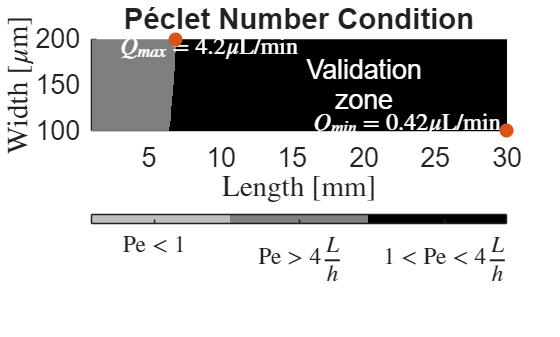

figure;

% Plot for all conditions in a single plot
hold on;
imagesc(l_vec*1e3, w_vec*1e6, Pe_cond); hold on
% colormap([0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.0072 0.4470 0.7410]); % Colors for 0, -1, and 1
colormap([0.75, 0.75, 0.75; 0.5, 0.5, 0.5; 0, 0, 0]); % Colors for 0, -1, and 1
caxis([-1 1]); % Set color axis limits to match Pe_cond values

text(20,150,{'Validation', 'zone'},'FontSize',fontsize,'Color','w','HorizontalAlignment','center');

text(l_vec(Q_min_l_idx-120)*1e3,w_vec(Q_min_w_idx+40)*1e6,{strcat('$Q_{min}=',num2str(Q_min*6e10,2),' \mu$L/min')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');
text(l_vec(Q_max_l_idx+40)*1e3,w_vec(Q_max_w_idx-40)*1e6,{strcat('$Q_{max}=',num2str(Q_max*6e10,2),' \mu$L/min')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

plot(l_vec(Q_min_l_idx)*1e3, w_vec(Q_min_w_idx)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
plot(l_vec(Q_max_l_idx)*1e3, w_vec(Q_max_w_idx)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);


% Create a colorbar and set its ticks and labels
cb = colorbar('Ticks', [-0.7, 0, 0.7], 'TickLabels', {'$\mathrm{Pe}<1$', '$\mathrm{Pe}>4\frac{L}{h}$', '$1<\mathrm{Pe}<4\frac{L}{h}$'}, 'TickLabelInterpreter', 'latex', 'FontSize', fontsize-3,'Location','southoutside');
% cb.Layout.Tile='south';

% Set the color of the colorbar with transparency
%set(colorbarHandle, 'alpha', 0.5); % RGBA format, where A is the alpha value
%alpha(0.5);

xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 w_vec(1)*1e6 w_vec(end)*1e6])
set(gca, 'YDir', 'normal');
title('Péclet Number Condition');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

### Peak time and peak amplitude vs width and length

Q_min=inf;
Q_max=-inf;

syms t

%length of the pipe
total_points=1e2;
w_vec=linspace(100e-6,200e-6,total_points);%selected based on the mixer dimenssion in [4, Fig. 3]
l_vec=linspace(7,30,total_points)*1e-3;%selected based on the Peclet number condition

%defining the time interval
total_points_time=1e2;
t_ini=1e-7;
t_end=10;
t_vector = linspace(t_ini,t_end,total_points_time);
time_sampling=t_vector(2)-t_vector(1);

h_amp=zeros(length(w_vec),length(l_vec));
h_tau=zeros(length(w_vec),length(l_vec));

p0=441.46

p0 = 441.4600


Q=Q_inlet_CNN; 

for i_w=1:length(w_vec)

    i_w/length(w_vec)*100

    for i_l=1:length(l_vec)

        %Hydraulic Resistance
        R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));

        %Volumetric flow
        Q=p0/R;

        %Mean velocity
        %Circular channel of radius r_vec(i_r) [2, pag. 54]
        % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q/(w_vec(i_w)*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        D_eff=D_coeff*(1+1/200*Pe^2);      

        %Validating the diffusion within the pipe
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            h_tau(i_w,i_l)=l_vec(i_l)/v_char-2*D_eff/v_char;
            %Evaluating the concentration of the straigth channel
            c=1./2.*erfc((l_vec(i_l)-v_char*t)./(2*sqrt(D_eff*t)));
            %Evaluating the channel impulse response
            h=diff(c,t);
            h_amp(i_w,i_l)=subs(h,h_tau(i_w,i_l));
            %for validation purposes only
            % figure;
            % figure;plot(t_vector,subs(h,t_vector)); grid on;
            % h_vs_t=subs(h,t_vector);
            % [h_amp(i_w,i_l),idx]=max(h_vs_t);
            % h_tau(i_w,i_l)=t_vector(idx);
            %Fiding the peak of the channel ımpulse response

            if(Q<Q_min)
                Q_min=Q;
                Q_min_w_idx=i_w;
                Q_min_l_idx=i_l;
            end

            if(Q>Q_max)
                Q_max=Q;
                Q_max_w_idx=i_w;
                Q_max_l_idx=i_l;
            end

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            disp(['Concentration is not constant along the x-axis, Pe=',num2str(double(Pe)),' is larger than ',num2str(4*l_vec(i_l)/height_pipe)])
            i_w
            i_l


        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            disp(['Diffusion hasn''t occurred along the axis, Pe=',num2str(double(Pe)),' is less than ',num2str(sqrt(48))])
            i_w
            i_l

        end
    end
end

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7.0000

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14.0000

ans = 15

ans = 16

ans = 17

ans = 18

ans = 19

ans = 20

ans = 21

ans = 22

ans = 23

ans = 24

ans = 25

ans = 26

ans = 27

ans = 28.0000

ans = 29.0000

ans = 30

ans = 31

ans = 32

ans = 33

ans = 34

ans = 35

ans = 36

ans = 37

ans = 38

ans = 39

ans = 40

ans = 41

ans = 42

ans = 43

ans = 44

ans = 45

ans = 46

ans = 47

ans = 48

ans = 49

ans = 50

ans = 51

ans = 52

ans = 53

ans = 54

ans = 55.0000

ans = 56.0000

ans = 57.0000

ans = 58.0000

ans = 59

ans = 60

ans = 61

ans = 62

ans = 63

ans = 64

ans = 65

ans = 66

ans = 67

ans = 68

ans = 69

ans = 70

ans = 71

ans = 72

ans = 73

ans = 74

ans = 75

ans = 76

ans = 77

ans = 78

ans = 79

ans = 80

ans = 81

ans = 82

ans = 83

ans = 84

ans = 85

ans = 86

ans = 87

ans = 88

ans = 89

ans = 90

ans = 91

ans = 92

ans = 93

ans = 94

ans = 95

ans = 96

ans = 97

ans = 98

ans = 99

ans = 100

### Length and width of the three pipes

%Setting the sampling time
tau_sample=9.5

tau_sample = 9.5000


%find the coordinates for the tau sample
%Pipe 1
[~,idx]=min(abs(h_tau(:)-tau_sample));
% Get row and column from linear index
[row, col] = ind2sub(size(h_tau), idx);
L_1=l_vec(col)

L_1 = 0.0209

w_1=w_vec(row)

w_1 = 1.7980e-04

R_1=12*mu*L_1/(1-0.63*height_pipe/w_1)*1/(height_pipe^3*w_1);
Q_1=p0/R_1*6e10

Q_1 = 0.9034



%Pipe 2
[~,idx]=min(abs(h_tau(:)-2*tau_sample));
% Get row and column from linear index
[row, col] = ind2sub(size(h_tau), idx);
L_2=l_vec(col)

L_2 = 0.0293

w_2=w_vec(row);

%Pipe 3
[~,idx]=min(abs(h_tau(:)-3*tau_sample));
% Get row and column from linear index
[row, col] = ind2sub(size(h_tau), idx);
L_3=l_vec(col)

L_3 = 0.0300

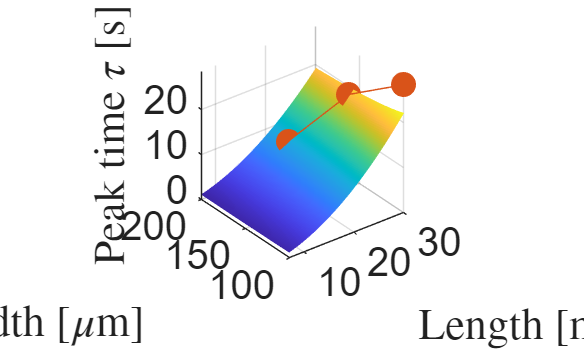

w_3=w_vec(row);


% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, w_vec*1e6, h_tau);hold on;
% Superposing the tau_coords on the plot
plot3([L_1 L_2 L_3]*1e3, [w_1 w_2 w_3]*1e6, tau_sample*[1 2 3], 'o-',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');

s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak time $\tau$ [s]','Interpreter','latex');
% title('Pipe 1')
%axis([l_vec(1)*1e3 l_vec*1e3 w_vec(1)*1e6 w_vec*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction


%Pipe 1
%Flow to the pipe 1 in a single connection
%resistance of the rectangular Pipe 1
R_1=12*mu_Water*L_1/(1-0.63*height_pipe/w_1)*(1/(height_pipe^3*w_1))

R_1 = 2.9320e+13

Q_1=p0/R_1;
Q_1_uL_min=Q_1*6e10

Q_1_uL_min = 0.9034


%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_1/(w_1*height_pipe)

v_char = 0.0022


%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff

Pe = 170.9034


%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2)

D_eff = 7.2050e-08

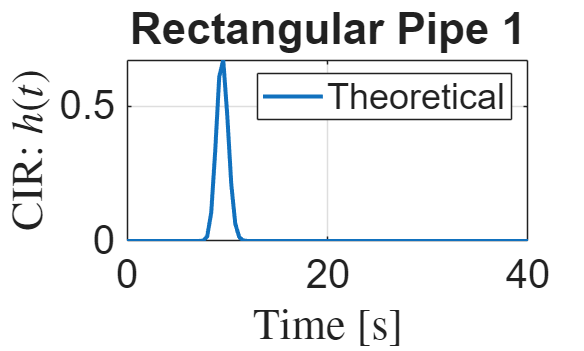


time=0:time_delta:time_simul;
%Evaluating the concentration of the straigth channel
conc_Pipe_1_Theo=1./2.*erfc((L_1-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_1_Theo=gradient(conc_Pipe_1_Theo,time);

figure;
plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
title("Rectangular Pipe 1")
set(gca,'FontSize',fontsize);
legend({'Theoretical','COMSOL'},'Location','northeast');

# CAD design of the CNN-like structure

**Description:** This code evaluates the coordinates for the upper lines and lower lines for each pipe. As represented on Fig. 1, we define each pipe coordinates with points.

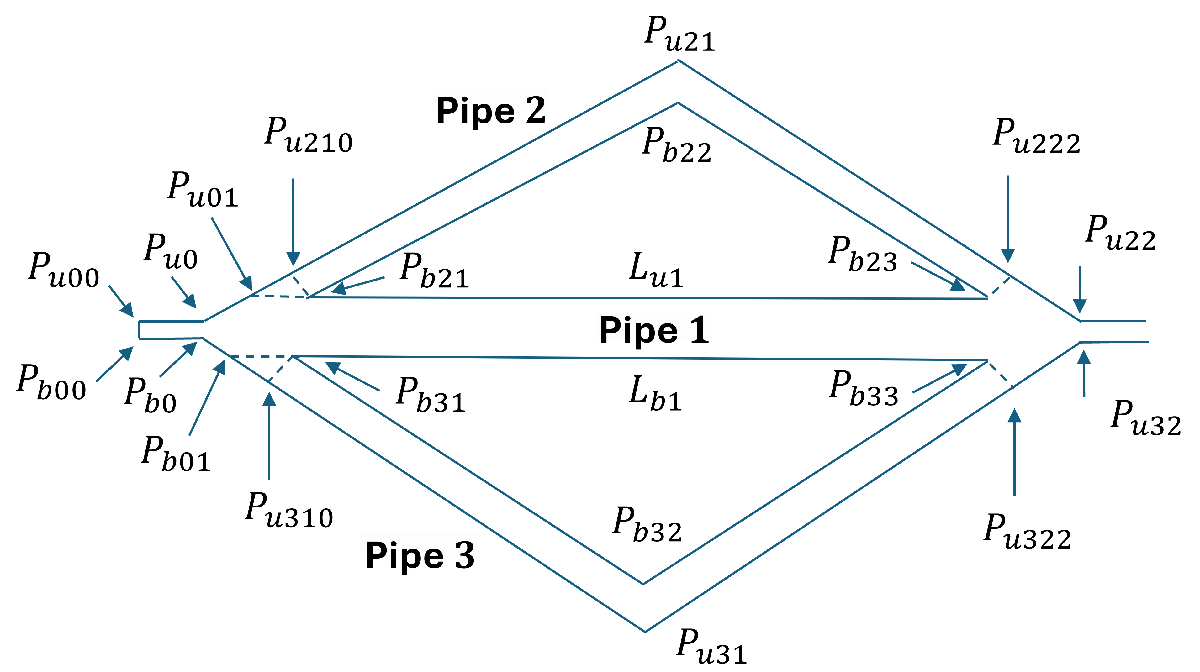

Figure 1: Reference points on the design.

## Reference coordinates

%this reference coordinates are coming from the original CAD desing. This
%two points reference refer to the pipe just after the mixer on the
%transmitter side. See Fig. 1.
P_u0=[-42.36063776 1.75826183]*1e-3;
P_b0=[-42.36063776 1.65926683]*1e-3;
%width for the mixer pipe, this is taken from [4]
w_0=P_u0(2)-P_b0(2);

fprintf('P_u0\n')

P_u0


fprintf('%.8f', P_u0(1)*1e3);   % fixed-point with 15 decimals

-42.36063776

fprintf('%.8f', P_u0(2)*1e3);   % fixed-point with 15 decimals

1.75826183


fprintf('P_b0\n')

P_b0


fprintf('%.8f', P_b0(1)*1e3);   % fixed-point with 15 decimals

-42.36063776

fprintf('%.8f', P_b0(2)*1e3);   % fixed-point with 15 decimals

1.65926683

## Restarting the reference coordinates

%length of the inlet
L_0=210e-6;

P_b00=[0 0];
P_u00=P_b00+[0 w_0]

P_u00 = 1.0e-04 *

         0    0.9899



fprintf('P_u00\n')

P_u00


fprintf('%.8f', P_u00(1)*1e3);   % fixed-point with 15 decimals

0.00000000

fprintf('%.8f', P_u00(2)*1e3);   % fixed-point with 15 decimals

0.09899500


fprintf('P_b0\n')

P_b0


fprintf('%.8f', P_b00(1)*1e3);   % fixed-point with 15 decimals

0.00000000

fprintf('%.8f', P_b00(2)*1e3);   % fixed-point with 15 decimals

0.00000000



P_b0=P_b00+[L_0 0];
P_u0=P_b0+[0 w_0];

fprintf('P_u0\n')

P_u0


fprintf('%.8f', P_u0(1)*1e3);   % fixed-point with 15 decimals

0.21000000

fprintf('%.8f', P_u0(2)*1e3);   % fixed-point with 15 decimals

0.09899500


fprintf('P_b0\n')

P_b0


fprintf('%.8f', P_b0(1)*1e3);   % fixed-point with 15 decimals

0.21000000

fprintf('%.8f', P_b0(2)*1e3);   % fixed-point with 15 decimals

0.00000000

## Pipe 2 coordinates

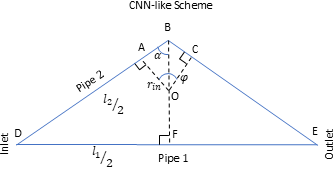

Figure 2: Reference angles within the pipe.

%heigth of the pipe
alpha=asin(L_1/L_2);
varphi_2=2*(pi-pi/2-alpha);
h_2=sqrt((L_2/2)^2-(L_1/2)^2);

P_u21=P_u0+[L_1/2 h_2];
fprintf('P_u21\n')

P_u21


fprintf('%.8f', P_u21(1)*1e3);   % fixed-point with 15 decimals

10.71000000

fprintf('%.8f', P_u21(2)*1e3);   % fixed-point with 15 decimals

0.09899500


%Calculating the point P_u01
%evaluating the line P_u0 to P_u21
m=(P_u21(2)-P_u0(2))/(P_u21(1)-P_u0(1))

m = 0.0000 + 0.4280i

b=P_u21(2)-m*P_u21(1)
P_u01(2)=P_u0(2)+w_1/2;
P_u01(1)=(P_u01(2)-b)/m;
% fprintf('P_u01\n')
% fprintf('%.8f', P_u01(1)*1e3);   % fixed-point with 15 decimals
% fprintf('%.8f', P_u01(2)*1e3);   % fixed-point with 15 decimals

P_b21=P_u01+[w_2/h_2*L_2/2 0];
fprintf('P_b21\n')
fprintf('%.8f', P_b21(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b21(2)*1e3);   % fixed-point with 15 decimals

P_b22=P_u21+[0 -w_2/sin(alpha)];
fprintf('P_b22\n')
fprintf('%.8f', P_b22(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b22(2)*1e3);   % fixed-point with 15 decimals

L_u1=2*(P_b22(1)-P_b21(1));
P_b23=P_b21+[L_u1 0];
fprintf('P_b23\n')
fprintf('%.8f', P_b23(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b23(2)*1e3);   % fixed-point with 15 decimals

P_u22=P_u0+[L_1 0];
fprintf('P_u22\n')
fprintf('%.8f', P_u22(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_u22(2)*1e3);   % fixed-point with 15 decimals

% %Calculating the point P_u222
% %evaluating the line P_u21 to P_u22
% m=(P_u21(2)-P_u22(2))/(P_u21(1)-P_u22(1))
% b=P_u21(2)-m*P_u21(1)
% mA = -1/m; % slope of perpendicular to line P_u21 to Pu22 
% P_u222(1) = (b - P_b23(2) + mA*P_b23(1)) / (mA - m);
% P_u222(2) = m*P_u222(1) + b;

%Calculating the point P_u222 with a mixer
%evaluating the line P_u21 to P_u22
P_u21=[-0.031861 0.012205];%measured from COMSOL_3D_Design_1_1_Transmitter_CNN
P_u22=[-0.021361 0.001758];%measured from COMSOL_3D_Design_1_1_Transmitter_CNN
P_b23=[-0.021641 0.001815];%measured from COMSOL_3D_Design_1_1_Transmitter_CNN
m=(P_u21(2)-P_u22(2))/(P_u21(1)-P_u22(1))
b=P_u21(2)-m*P_u21(1)
mA = -1/m; % slope of perpendicular to line P_u21 to Pu22 
P_u222(1) = (b - P_b23(2) + mA*P_b23(1)) / (mA - m);
P_u222(2) = m*P_u222(1) + b;

%Calculating the point P_u210
P_u0=[-0.042361 0.001758]; %measured in COMSOL_3D_CNN_Design_1_1_Transmitter_CNN
P_u21=[-0.031861 0.012205]; %measured in COMSOL_3D_CNN_Design_1_1_Transmitter_CNN
P_b21=[-0.04208 0.001815]; %measured in COMSOL_3D_CNN_Design_1_1_Transmitter_CNN
%evaluating the line P_u0 to P_u21
m=(P_u0(2)-P_u21(2))/(P_u0(1)-P_u21(1))
b=P_u0(2)-m*P_u0(1)
mA = -1/m; % slope of perpendicular to line P_u21 to Pu22 
P_u210(1) = (b - P_b21(2) + mA*P_b21(1)) / (mA - m);
P_u210(2) = m*P_u210(1) + b;


## Pipe 3 coordinates

%heigth of the pipe
alpha=asin(L_1/L_3);
varphi_3=2*(pi-pi/2-alpha);
h_3=sqrt((L_3/2)^2-(L_1/2)^2);


P_u31=P_b0+[L_1/2 -h_3];
fprintf('P_u31\n')
fprintf('%.8f', P_u31(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_u31(2)*1e3);   % fixed-point with 15 decimals

%Calculating the point P_b01
%evaluating the line P_b0 to P_u31
m=(P_u31(2)-P_b0(2))/(P_u31(1)-P_b0(1))
b=P_u31(2)-m*P_u31(1)
P_b01(2)=P_b0(2)-w_1/2;
P_b01(1)=(P_b01(2)-b)/m;
% fprintf('P_b01\n')
% fprintf('%.8f', P_b01(1)*1e3);   % fixed-point with 15 decimals
% fprintf('%.8f', P_b01(2)*1e3);   % fixed-point with 15 decimals

P_b31=P_b01+[w_3/h_3*L_3/2 0];
fprintf('P_b31\n')
fprintf('%.8f', P_b31(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b31(2)*1e3);   % fixed-point with 15 decimals

P_b32=P_u31+[0 w_3/sin(alpha)];
fprintf('P_b32\n')
fprintf('%.8f', P_b32(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b32(2)*1e3);   % fixed-point with 15 decimals

L_b1=2*(P_b32(1)-P_b31(1));
P_b33=P_b31+[L_b1 0];
fprintf('P_b33\n')
fprintf('%.8f', P_b33(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b33(2)*1e3);   % fixed-point with 15 decimals

P_u32=P_b0+[L_1 0];
fprintf('P_u32\n')
fprintf('%.8f', P_u32(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_u32(2)*1e3);   % fixed-point with 15 decimals

%Calculating the point P_u322
%evaluating the line P_u31 to Pu32
P_u31=[-0.031861 -0.012389] %meaured in COMSOL_3D_CNN_Design_1_1_Transmitter_CNN
P_u32=[-0.021361 0.001659] %meaured in COMSOL_3D_CNN_Design_1_1_Transmitter_CNN
P_b33=[-0.021652 0.001603] %meaured in COMSOL_3D_CNN_Design_1_1_Transmitter_CNN

m=(P_u31(2)-P_u32(2))/(P_u31(1)-P_u32(1))
b=P_u31(2)-m*P_u31(1)
%evaluating the line P_u31 to P_u32
mA = -1/m; % slope of perpendicular to line P_u31 to Pu32 
P_u322(1) = (b - P_b33(2) + mA*P_b33(1)) / (mA - m);
P_u322(2) = m*P_u322(1) + b;

%Calculating the point P_u310
%evaluating the line P_b0 to P_u31
P_b0=[-0.042361 0.001659] %meaured in COMSOL_3D_CNN_Design_1_1_Transmitter_CNN
P_u31=[-0.031861 -0.012389] %meaured in COMSOL_3D_CNN_Design_1_1_Transmitter_CNN
P_b31=[-0.042069 0.001603] %meaured in COMSOL_3D_CNN_Design_1_1_Transmitter_CNN
m=(P_b0(2)-P_u31(2))/(P_b0(1)-P_u31(1))
b=P_b0(2)-m*P_b0(1)
%evaluating the line P_u31 to Pu32
mA = -1/m; % slope of perpendicular to line P_b0 to P_u31 
P_u310(1) = (b - P_b31(2) + mA*P_b31(1)) / (mA - m);
P_u310(2) = m*P_u310(1) + b;

## Pipe 1 coordinates

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end


P_b11=P_b0-[0 w_1/2];
fprintf('P_b11\n')
fprintf('%.8f', P_b11(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b11(2)*1e3);   % fixed-point with 15 decimals

P_b12=P_b11+[L_1 0];
fprintf('P_b12\n')
fprintf('%.8f', P_b12(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b12(2)*1e3);   % fixed-point with 15 decimals


## Outlet coordinates

outlet_length=L_0;
P_u11=P_u22+[outlet_length 0];
fprintf('P_u11\n')
fprintf('%.8f', P_u11(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_u11(2)*1e3);   % fixed-point with 15 decimals

P_b11=P_u32+[outlet_length 0];
fprintf('P_b13\n')
fprintf('%.8f', P_b11(1)*1e3);   % fixed-point with 15 decimals
fprintf('%.8f', P_b11(2)*1e3);   % fixed-point with 15 decimals


## Polygons

## saving the coordinates within a CSV file

%Upper polygon
% Stack all vertices row by row
coords = [P_b21; P_b22; P_b23; P_b21];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_upper.csv'); % build full path safely
writematrix(coords, outputFile);

%Bottom polygon
% Stack all vertices row by row
coords = [P_b31; P_b32; P_b33; P_b31];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_bottom.csv'); % build full path safely
writematrix(coords, outputFile);

%Outer polygon
% Stack all vertices row by row
coords = [P_u00; P_u0; P_u21; P_u22; P_u11; P_b11; P_u32; P_u31; P_b0; P_b00];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_outer.csv'); % build full path safely
writematrix(coords, outputFile);

#### Saving variables 

T = readtable('parameters_2D.csv', 'TextType','string');

%height of Pipes 
newRow = makeRow(height_pipe, "height of pipes", "um", 1e6);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(height_pipe)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile);

%Length Pipe 1
newRow = makeRow(L_1, "Length of Pipe 1", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(L_1)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 1
newRow = makeRow(w_1, "Width of Pipe 1", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_1)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);


%Length Pipe 2
newRow = makeRow(L_2, "Length of Pipe 2", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(L_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 2
newRow = makeRow(w_2, "Width of Pipe 2", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);


%Length Pipe3
newRow = makeRow(L_3, "Length of Pipe 3", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(L_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 3
newRow = makeRow(w_3, "Width of Pipe 3", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b23
P_b23_x=P_b23(1)
newRow = makeRow(P_b23_x, "x-Coordinates for P_b23", "m",1);
%Delete any existing row with the same Name
T(T.Variables== string(getVarName(P_b23_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b23_y=P_b23(2)
newRow = makeRow(P_b23_y, "y-Coordinates for P_b23", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b23_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b33
P_b33_x=P_b33(1)
newRow = makeRow(P_b33_x, "x-Coordinates for P_b33", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b33_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b33_y=P_b33(2)
newRow = makeRow(P_b33_y, "y-Coordinates for P_b33", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b33_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u222
P_u222_x=P_u222(1)
newRow = makeRow(P_u222_x, "x-Coordinates for P_u222", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u222_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u222_y=P_u222(2)
newRow = makeRow(P_u222_y, "y-Coordinates for P_u222", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u222_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u322
P_u322_x=P_u322(1)
newRow = makeRow(P_u322_x, "x-Coordinates for P_u322", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u322_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u322_y=P_u322(2)
newRow = makeRow(P_u322_y, "y-Coordinates for P_u322", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u322_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u210
P_u210_x=P_u210(1)
newRow = makeRow(P_u210_x, "x-Coordinates for P_u210", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u210_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u210_y=P_u210(2)
newRow = makeRow(P_u210_y, "y-Coordinates for P_u210", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u210_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b21
P_b21_x=P_b21(1)
newRow = makeRow(P_b21_x, "x-Coordinates for P_b21", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b21_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b21_y=P_b21(2)
newRow = makeRow(P_b21_y, "y-Coordinates for P_b21", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b21_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b31
P_b31_x=P_b31(1)
newRow = makeRow(P_b31_x, "x-Coordinates for P_b31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b31_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b31_y=P_b31(2)
newRow = makeRow(P_b31_y, "y-Coordinates for P_b31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b31_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u310
P_u310_x=P_u310(1)
newRow = makeRow(P_u310_x, "x-Coordinates for P_u310", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u310_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u310_y=P_u310(2)
newRow = makeRow(P_u310_y, "y-Coordinates for P_u310", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u310_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u31
P_u31_x=P_u31(1)
newRow = makeRow(P_u31_x, "x-Coordinates for P_u31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u31_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u31_y=P_u31(2)
newRow = makeRow(P_u31_y, "y-Coordinates for P_u31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u31_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Length Pipe 2
newRow = makeRow(L_2, "Length of Pipe 2", "m", 1);
%Delete any existing row with the same Name

T(T.Variables == string(getVarName(L_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 2
newRow = makeRow(w_2, "width of Pipe 2", "m", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Angle Pipe 2
newRow = makeRow(varphi_2, "Angle of Pipe 2", "rad", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(varphi_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Length Pipe 3
newRow = makeRow(L_3, "Length of Pipe 3", "m", 1);
%Delete any existing row with the same Name

T(T.Variables == string(getVarName(L_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 3
newRow = makeRow(w_3, "width of Pipe 3", "m", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Angle Pipe 2
newRow = makeRow(varphi_3, "Angle of Pipe 3", "rad", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(varphi_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

### Normal vectors to defined planes

%vector normal ot the input plane defined by the three points 
% Define three points (row vectors)
P1 = [P_u310_x, P_u310_y, 0];
P2 = [P_u310_x, P_u310_y, height_pipe];
P3 = [P_b31_x, P_b31_y, 0];

% Vectors lying in the plane
v1 = P2 - P1;
v2 = P3 - P1;

% Cross product -> normal vector
n = cross(v1, v2);

% Normalize -> orthonormal vector
n_Pipe_3_inlet = n / norm(n);

disp('The orthonormal vector to the plane is:');
disp(n_Pipe_3_inlet);

%n_Pipe_3_inlet
n_Pipe_3_inlet_x=n_Pipe_3_inlet(1)
newRow = makeRow_no_unit(n_Pipe_3_inlet_x, "x-Coordinates for n_Pipe_3_inlet");
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(n_Pipe_3_inlet_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

n_Pipe_3_inlet_y=n_Pipe_3_inlet(2)
newRow = makeRow_no_unit(n_Pipe_3_inlet_y, "y-Coordinates for n_Pipe_3_inlet");
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(n_Pipe_3_inlet_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

n_Pipe_3_inlet_z=n_Pipe_3_inlet(3)
newRow = makeRow_no_unit(n_Pipe_3_inlet_z, "y-Coordinates for n_Pipe_3_inlet");
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(n_Pipe_3_inlet_z)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);



function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end

function trow = makeRow(var, description, unit, scale)
    name = inputname(1);
    valStr = sprintf('%g[%s]', var*scale, unit);
    trow = table(string(name), string(valStr), string(description), ...
                 'VariableNames', {'Name','Value','Description'});
end

function trow = makeRow_no_unit(var, description)
    name = inputname(1);
    valStr = sprintf('%g', var);
    trow = table(string(name), string(valStr), string(description), ...
                 'VariableNames', {'Name','Value','Description'});
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, “Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section,” *Mathematical and Computer Modelling*, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: [10.1016/j.mcm.2006.11.029](https://doi.org/10.1016/j.mcm.2006.11.029). 

[4] Murat paper